Reto 1: Parte 2

Profundización II: Electromedicina

Restauración de imágenes de leucocitos de un canino.

Leandro Ramos - 219160260

Brandon Rosero - 219160289

Se inicializa el código limpiando la consola, las variables y cerrando todas las imágenes abiertas previamente.

clear; close all; clc

Se hace la obtención de la imágen.

I=imread("Leucocitos\S2_1.bmp");

Se extrae la capa roja para trabajarla.

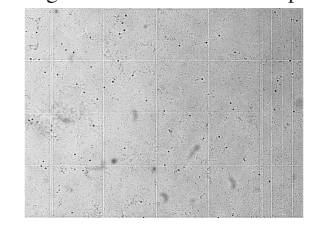

I=I(:,:,1);
imshow(I,[])
title('Imagen obtenida del microscopio','fontsize',14,'interpreter','latex');

Se aplica transformada rápida de Fourier a la capa roja

If=(fft2(I));

El algorítmo que define la transformada rápida de fourier es el siguiente $[1]$:

                             $X[k]=\sum_{n=0}^{N-1}X_0[n]\, e^{-\frac{2\pi i}{N} kn}.

$                         (1)

donde $X_0[n]$ es una señal discreta en el tiempo.

imshow(real(log(1+(If))),[])
title('Espectro de Fourier de la imagen','fontsize',14,'interpreter','latex')

Como no se determina un patrón de interferencia en el espectro de fourier de la imágen, se aplica "fftshift" al espectro para centrar las frecuencias en cero.

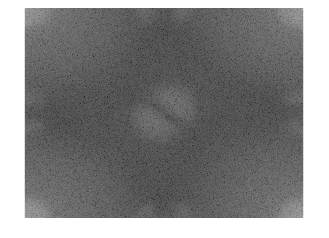

If1=(fftshift(If));
%imshow(real(log(1+(If1))),[])
title('Espectro de Fourier con frecuencias centradas de la imagen','fontsize',14,'interpreter','latex')

Se crea un filtro notch correspondiente para los espectros determinados.

Primero se determina que el tamaño del filtro será igual al del espectro.

[P , Q]=size(If);

Se crea una matriz llena de ceros con el tamaño de la imágen original.

D=zeros(P,Q); 

H=masnotch(I,10,30);

Se procede a visualizar el resultado.

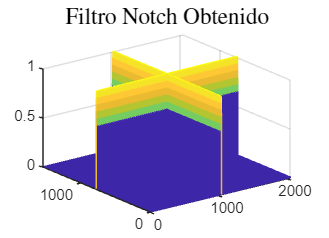

H(H>=1)=1;
mesh(H)
title("Filtro Notch Obtenido",'fontsize',14,'interpreter','latex')

Se realiza el centrado de frecuencias en cero con la función "fftshift" y se observa lo obtenido.

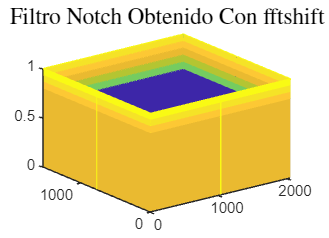

H1=fftshift(H);
mesh(H1)
title('Filtro Notch Obtenido Con fftshift','fontsize',14,'interpreter','latex')

Se aplica el filtro en el dominio de la frecuencia de la siguiente manera:

Bf=If.*H1;

Se aplica la transformada Inversa de fourier a la operación anteriormente hecha de la siguiente manera:

I2=(ifft2(Bf)); 

Matemáticamente hablando es la siguiente[1]:

                           $X_0[n]=\frac{1}{N} \sum_{n=0}^{N-1}X[k]\, e^{\frac{2\pi i}{N} kn}.$                  (2)

Se obtiene la parte real de la transformada inversa que corresponde a la imágen:

I2=real(I2);

Se calcula el función de ponderación definida en clase de la siguiente forma:

                              $\frac{\overline{𝑔(𝑥, 𝑦)𝜂(𝑥, 𝑦)}-\overline{g}(x,y) \overline{𝜂}(x,y)}{\overline{𝜂2(x,y)} - \overline{𝜂(x,y)} ^{2} }$              (3)

Donde g(x,y) es la imágen a la cual restar el patrón de interferencia y 𝜂(x,y) es el patrón de interferencia.

In = notch_optimo(I,I2,1); % funcion de notch optimo

Aplicación del filtro Wiener en la imágen sin interferencias

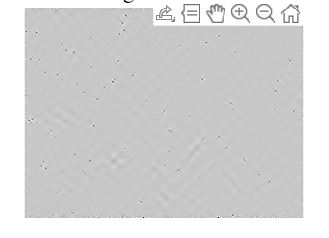

[imagenfiltrada, PR] = wiener2(In, [40 40]); 
IFilt=escalar(imagenfiltrada,255);
imshow(uint8(IFilt));
title("Imagen obtenida",'fontsize',14,'interpreter','latex')

Se extrae el fondo de la imágen para visualizar lo que se eliminó

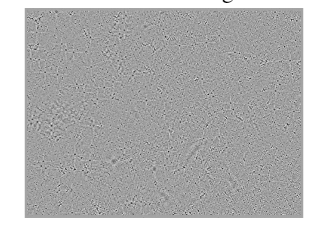

Iop=double(In)-imagenfiltrada;
IFond=escalar(Iop,255);
imshow(uint8(IFond));
title("Fondo de la imagen",'fontsize',14,'interpreter','latex')

Referencias

[1]. Ramírez Cortés, Juan Manuel; Gómez Gil, María del Pilar; Báez López, David (marzo-abril de 1998). "El algoritmo de la Transformada Rápida de Fourier y su controvertido origen". *Ciencia y Desarrollo* **24** (139): 70-77. 

[2] Rafael C. Gonzalez y Richard E. Woods (2018) Digital Image Processing, Pearson, 4th ed, University of Tennessee.

[3] Rangaraj M. Rangayyan (2015) Biomedical Signal Analysis, The Institute of Electrical and Electronics Engineers, Inc., 2nd ed.